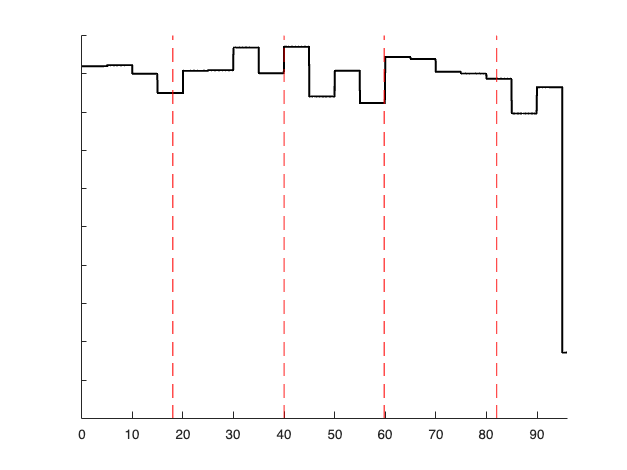

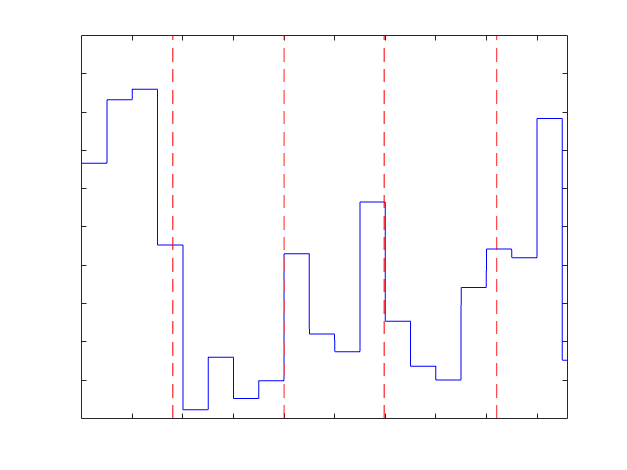

%Load in Classified Attentiveness and Screen Engagement Data
load('Bard.mat')
%Desired Window Size
window = 300*30;
%Identify epoch times
Epochs = {
'Experiment', 'Start', 'WM1','M1','EC','M2','WM2','hF','tF';
'0527',3601,34734,90001,142500,167437,179411,attentiveness0527,touches0527,
'0528',7201,39585,79201,114853,154801,180001,attentiveness0528,touches0528,
'0529',3242,42633,93601,121900,159021,177770,attentiveness0529,touches0529,
'0530',3601,42855,75893,107996,144306,172357,attentiveness0530,touches0530,
'0604',10801,46800,97201,121652,151617,179628,attentiveness0604,touches0604,
'0610',3601,34624,69400,107185,133982,165600,attentiveness0610,touches0610,
'0612',4633,43168,76246,103579,131321,180000,attentiveness0612,touches0612,
'0613',3601,35998,55575,109623,141936,161988,attentiveness0613,touches0613,
'0614',4081,41267,68778,100068,129997,165217,attentiveness0614,touches0614,
'0618',7474,41183,79468,106771,135142,168546,attentiveness0618,touches0618,
'0619',3823,32644,54001,92786,127931,161457,attentiveness0619,touches0619,
'0620',4312,33922,79488,103780,131521,157682,attentiveness0620,touches0620,
'0621',4989,27818,45247,100767,120954,157458,attentiveness0621,touches0621,
'0624',3601,34891,63114,97174,121466,163504,attentiveness0624,touches0624,
'0625',5739,32401,49316,99767,131389,164308,attentiveness0625,touches0625,
'0626',6032,32393,63760,124203,143998,169142,attentiveness0626,touches0626,
'0628',4212,28770,74834,114245,134980,164013,attentiveness0628,touches0628,
'0715',4121,24491,58712,104376,126635,159764,attentiveness0715,touches0715,
'0716',11723,28775,69770,114318,145650,194390,attentiveness0716,touches0716,
'0717',3600,32396,66391,109873,139082,160854,attentiveness0717,touches0717,
'0718',3601,20021,68392,102806,140803,201601,attentiveness0718,touches0718,
'0719',6477,28772,73600,100043,128040,158363,attentiveness0719,touches0719,
'0722',5799,25151,95530,118796,168330,197502,attentiveness0722,touches0722,
'0723',4920,25197,34859,77189,112583,145665,attentiveness0723,touches0723,
'0725',6046,20390,49202,79192,100401,145878,attentiveness0725,touches0725,
'0726',3725,36896,96780,115170,132221,150379,attentiveness0726,touches0726,
'0729',3601,25201,45017,82765,117239,143960,attentiveness0729,touches0729,
'0730',19911,35987,66710,113167,126391,140400,attentiveness0730,touches0730,
'0731',6004,24848,80826,96002,124463,148867,attentiveness0731,touches0731,
'0801',4240,27444,49032,92486,124559,142577,attentiveness0801,touches0801,
'0802',9166,34492,63579,92294,113275,142575,attentiveness0802,touches0802,
};
%Look at every session as itself
dataOverview(Epochs,window)

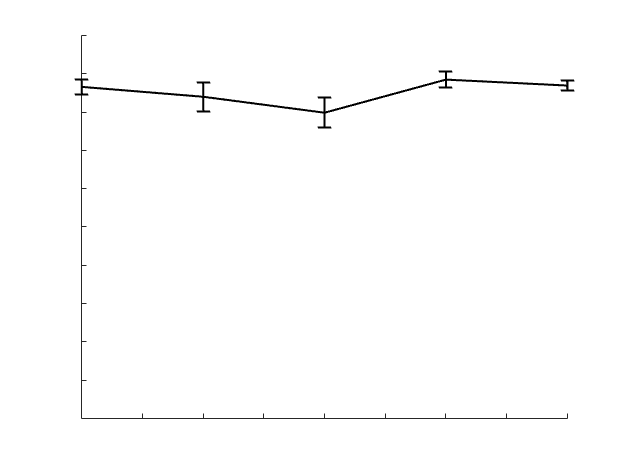

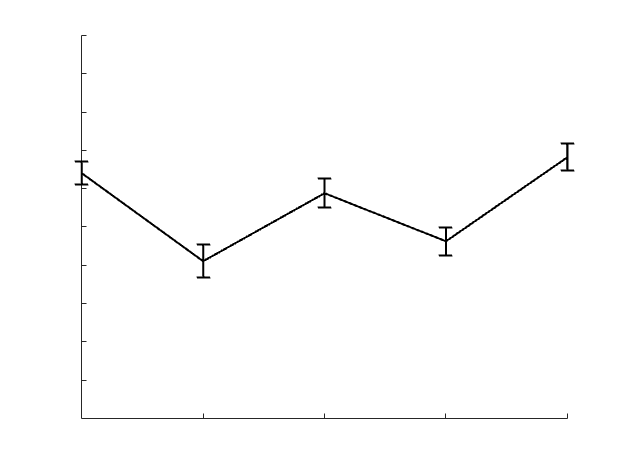

%Look at each task across sessions
[hF,tF] = dataSpecific(Epochs);



function [hF,tF] = dataSpecific(Epochs)
    % Extract relevant data from the Epoch cell
    num_epochs = size(Epochs, 1) - 1; % Number of epochs (ignore header row)
    
    hF = zeros(num_epochs,5);
    tF = zeros(num_epochs,5);
    
    clf
    figure; % Create a figure for the subplots
    for i = 1:num_epochs 
        start = Epochs{i+1, 2};    % Start time
        WM1 = Epochs{i+1, 3};      % WM1 time
        M1 = Epochs{i+1, 4};       % M1 time
        EC = Epochs{i+1, 5};       % EC time
        M2 = Epochs{i+1, 6};       % M2 time
        WM2 = Epochs{i+1, 7};      % WM2 time
        attentive = Epochs{i+1, 8};       % hF data
        touch = Epochs{i+1, 9};       % tF data

        timespot = [start,WM1,M1,EC,M2,WM2];

        for ii = 1:5
            hFdata = attentive(timespot(ii):timespot(ii+1));
            tFdata = touch(timespot(ii):timespot(ii+1));

            hF_value = (length(hFdata) - sum(hFdata))/length(hFdata);
            tF_value = (length(tFdata) - sum(tFdata))/length(tFdata);

            hF(i,ii) = 1-hF_value;
            tF(i,ii) = 1-tF_value;
        end
        
    end
    % Define labels for x-axis
    x_labels = {'WM1', 'M1', 'EC', 'M2', 'WM2'};
    
    % Calculate means and standard deviations across rows
    havg_values = mean(hF, 1);  % Mean across the 4 rows for each column
    herrors = std(hF, 0, 1);% Standard deviation across the 4 rows for each column

    tavg_values = mean(tF, 1);  % Mean across the 4 rows for each column
    terrors = std(tF, 0, 1);    % Standard deviation across the 4 rows for each column
    


    % subplot(2,1,1)
    figure
    hold on;
    % bar(1:length(havg_values), havg_values, 'FaceColor', 'none', 'EdgeColor', 'b', 'LineWidth', 1);
    errorbar(1:length(havg_values), havg_values, herrors/sqrt(31), 'k', 'linestyle', 'none', 'CapSize', 10,'LineWidth', 1.5)
    plot(1:length(havg_values), havg_values, 'k', 'LineWidth', 1.5);
    % Customize the axes
    ylim([0 1]); % Set y-axis limit between 0 and 1
    set(gca, 'XTickLabel', [])  % Remove all x-axis numerical values
    set(gca, 'YTickLabel', [])  % Remove all x-axis numerical values
    % ylim([0 1]); % Set y-axis limit between 0 and 1

    % ylabel('Unattentiveness Score');
    % title('Unattentiveness');
    
    hold off;

    % subplot(2,1,2)
    figure
    hold on;
    % bar(1:length(tavg_values), tavg_values, 'FaceColor', 'none', 'EdgeColor', 'b', 'LineWidth', 1);
    errorbar(1:length(tavg_values), tavg_values, terrors/sqrt(31), 'k', 'linestyle', 'none', 'CapSize', 10,'LineWidth', 1.5)
    plot(1:length(tavg_values), tavg_values, 'k', 'LineWidth', 1.5);
    % Customize the axes
    set(gca, 'XTick', 1:length(x_labels), 'XTickLabel', x_labels); % Set x-axis labels
    ylim([0 1]); % Set y-axis limit between 0 and 1
    set(gca, 'XTickLabel', [])  % Remove all x-axis numerical values
    set(gca, 'YTickLabel', [])  % Remove all x-axis numerical values

    % ylabel('Screen Engagement Score');
    % title('Screen Engagement');
    
    hold off;
end

function dataOverview(Epochs, window)
    % Extract relevant data from the Epoch cell
    num_epochs = size(Epochs, 1) - 1; % Number of epochs (ignore header row)
    
    figure; % Create a figure for the subplots
    % sgtitle('Bard')
    for i = 1:num_epochs 
        % Extract time and position markers for each experiment
        start = Epochs{i+1, 2};    % Start time
        WM1 = Epochs{i+1, 3};      % WM1 time
        M1 = Epochs{i+1, 4};       % M1 time
        EC = Epochs{i+1, 5};       % EC time
        M2 = Epochs{i+1, 6};       % M2 time
        WM2 = Epochs{i+1, 7};      % WM2 time
        attentive = Epochs{i+1, 8}(start:WM2);       % hF data
        touch = Epochs{i+1, 9}(start:WM2);       % tF data


        num_windows = ceil(length(attentive) / window);

        % Initialize the frequency vector
        hF = zeros(length(attentive), 1);
        tF = zeros(length(touch),1);
        
        for ii = 1:num_windows
            % Define the start and end of the current window
            start_idx = (ii - 1) * window + 1;
            end_idx = min(ii * window, length(attentive));
            
            % Calculate the frequency of true values in the current window
            hfreq_value = window - sum(attentive(start_idx:end_idx));
            hfreq_value = (window-hfreq_value)./window;

            tfreq_value = window - sum(touch(start_idx:end_idx));
            tfreq_value = (window-tfreq_value)./window;
            
            % Assign the frequency value to the corresponding indices in the freq vector
            hF(start_idx:end_idx) = hfreq_value;
            tF(start_idx:end_idx) = tfreq_value;
        end
        time = 1:length(attentive);
        time = time./30./60;
        
        % Plot the hF subplot
        % subplot(ceil(length(Epochs)/2), 2, i); % 4x2 layout, left for hF
        figure
        plot(time, hF, 'k','LineWidth',1.5); % Plot hF in blue
        hold on;
        % Plot vertical lines for WM1, M1, EC, M2
        xline((WM1-start)/30/60, 'r--', 'LineWidth', 1); % Red dashed line for WM1
        xline((M1-start)/30/60, 'r--', 'LineWidth', 1);  % Red dashed line for M1
        xline((EC-start)/30/60, 'r--', 'LineWidth', 1);  % Red dashed line for EC
        xline((M2-start)/30/60, 'r--', 'LineWidth', 1);  % Red dashed line for M2
        hold off;
        % title(['hF for Experiment ', Epochs{i+1, 1}]);
        % xlabel('Time (Minutes)');
        % ylabel('% time attentive');
        axis([0 max(time) 0 1])
        % set(gca, 'XTickLabel', [])  % Remove all x-axis numerical values
        set(gca, 'YTickLabel', [])  % Remove all x-axis numerical values
        box off 
        
        % Plot the tF subplot
        % subplot(ceil(length(Epochs)/2), 2, i+1); % 4x2 layout, right for tF
        figure
        plot(time, tF, 'b'); % Plot tF in blue
        hold on;
        % Plot vertical lines for WM1, M1, EC, M2
        xline((WM1-start)/30/60, 'r--', 'LineWidth', 1); % Red dashed line for WM1
        xline((M1-start)/30/60, 'r--', 'LineWidth', 1);  % Red dashed line for M1
        xline((EC-start)/30/60, 'r--', 'LineWidth', 1);  % Red dashed line for EC
        xline((M2-start)/30/60, 'r--', 'LineWidth', 1);  % Red dashed line for M2
        hold off;
        % title(['tF for Experiment ', Epochs{i+1, 1}]);
        % xlabel('Time (Minutes)');
        % ylabel('% time engaging');
        axis([0 max(time) 0 1])
        set(gca, 'XTickLabel', [])  % Remove all x-axis numerical values
        set(gca, 'YTickLabel', [])  % Remove all x-axis numerical values
    end
end